# Preparation

## path and filename setup

clear all
close all

indir = "C:\projects\emo_EEG\data_pipeline\mTRF\dataCND";
stim_fname = "dataStim_order1.mat";
% eeg_fnames = {'pre_dataSubJun_ica.mat'};
eeg_fnames = {'pre_dataSub1_ica.mat',...
              'pre_dataSub2_ica.mat',...
              'pre_dataSub3_ica.mat',...
              'pre_dataSub4_ica.mat',...
              'pre_dataSub5_ica.mat'};

## Data loading and preparation

nSubs = length(eeg_fnames);

% loading stimulus data
stim_path = fullfile(indir, stim_fname);
load(stim_path, 'stim')

% % normalization
% stim = cndNormalise(stim);

% load list of stimulus features
stimNames = stim.names;

# univariate forward TRF

## Step 0: Setup

setting up mTRF hyperparameter

tmin = -200;
tmax = 600;
lambdas = 10.^(-4:2:4); % small set of lambdas (quick)
% lambdas = 10.^(-6:1:6); % larger set of lambdas (slower)
dirTRF = 1; % forward TRF model

channel_option = 1;
prp_ch_idx = [2, 29, 31, 4, 27, 5, 26]; % ['AF3', 'AF4', 'Fz', 'F3', 'F4', 'FC1', 'FC2']
if channel_option    
    selected_ch_idx = prp_ch_idx;
else
    selected_ch_idx = 'all';
end
Xlims = [-50 400];

stimName = stimNames(1);
stimIdx = find(strcmp(stim.names,stimName));

if tmin > tmax
    disp('Warning: tmin > tmax; setting tmax=tmin for the analysis')
    tmax = tmin;
end

loading preprocessing EEG data 

sub_eegs = cell(1, nSubs);
for subIdx = 1:nSubs
    eeg_path = fullfile(indir, eeg_fnames{subIdx});
    load(eeg_path, 'eeg')
    eeg = cndNormalise(eeg);

    % match frequencies if needed
    if eeg.fs < stim.fs
        stim = cndDownsample(stim,eeg.fs);
    end
    
    [stim,eeg] = cndCheckStimNeural(stim,eeg);
    sub_eegs{subIdx} = eeg; % Store the normalized EEG data for each subject
end

select trials belong to specific conditions

% load stim conditions
audio_emotions = stim.emotions;
audio_speech_styles = stim.speech_styles;
audio_genders = stim.genders;
unique_emotions = unique(audio_emotions);
unique_speech_styles = unique(audio_speech_styles);
unique_genders = unique(audio_genders);

% condition selection
include_emotions =false;
include_speech_styles =false;
include_genders =false;
selected_emotion = unique_emotions(1);
selected_speech_style = unique_speech_styles(2);
selected_gender = unique_genders(2);

% start with all true
idx = true(1, numel(audio_emotions));
% apply emotion filter if selected
if include_emotions
    idx = idx & strcmp(audio_emotions, selected_emotion);
end
% apply speech style filter if selected
if include_speech_styles
    idx = idx & strcmp(audio_speech_styles, selected_speech_style);
end
% apply gender filter if selected
if include_genders
    idx = idx & strcmp(audio_genders, selected_gender);
end
match_idx = find(idx);

% use filter to trim Stim
stim_trim = stim;
stim_trim.filenames = stim.filenames(:, match_idx);
stim_trim.data = stim.data(:, match_idx);
stim_trim.emotions = audio_emotions(match_idx);
stim_trim.speech_styles = audio_speech_styles(match_idx);
stim_trim.genders = audio_genders(match_idx);
stim_trim.names = stimNames;
stim_trim.fs = stim.fs;

% use fileter to trim dataSubs
for subIdx = 1:nSubs
    eeg = sub_eegs{subIdx};
    eeg_trim = eeg;
    eeg_trim.data = eeg.data(:, match_idx);
    eeg_trim.origTrialPosition = eeg.origTrialPosition(:, match_idx);
    % Trim EEG data based on the matched indices
    sub_eegs_trim{subIdx} = eeg_trim;
end

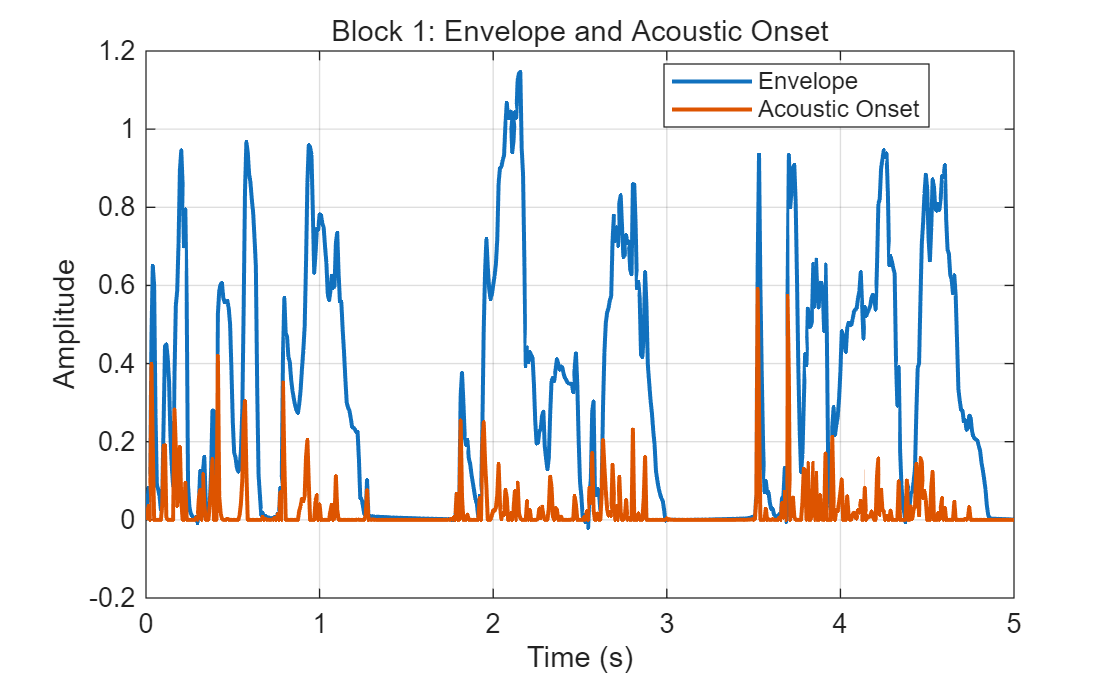

% find feature rows by name
env_idx = find(strcmp(stim_trim.names, 'Speech Envelope Vector'));
ac_onset_idx = find(strcmp(stim_trim.names, 'Acoustic Onset Vector'));

if isempty(env_idx)
    error('Speech Envelope Vector not found in stim_trim.names');
end
if isempty(ac_onset_idx)
    error('Acoustic Onset Vector not found in stim_trim.names');
end

% get block 1 data
block_idx = 1;
env = stim_trim.data{env_idx, block_idx};
ac_onset = stim_trim.data{ac_onset_idx, block_idx};

% force column vectors
env = env(:);
ac_onset = ac_onset(:);

% time axis
t = (0:length(env)-1) / stim_trim.fs;

% plot on same figure
figure;
plot(t, env, 'LineWidth', 1.5);
hold on;
plot(t, ac_onset, 'LineWidth', 1.5);
hold off;

xlabel('Time (s)');
xlim([0 5])
ylabel('Amplitude');
title('Block 1: Envelope and Acoustic Onset');
legend({'Envelope', 'Acoustic Onset'}, 'Location', 'best');
grid on;

## Step 1: Training

% Forward TRF (unregularised)
for subIdx = 1:nSubs
    eeg = sub_eegs_trim{subIdx};

    model = mTRFtrain(stim_trim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,0,'verbose',0);

    % plot TRF weights
    disp(eeg_fnames{subIdx})
    disp("Forward TRF weights (without regularisation)")

    figure;
    subplot(1,2,1)
    mTRFplot(model,'trf', [], selected_ch_idx, Xlims);
    title('TRF weights')
    grid on
    
    % Plot GFP
    subplot(1,2,2)
    mTRFplot(model,'gfp',[],selected_ch_idx, Xlims);
    title('TRF Global Field Power')
    grid on
    
    modelAll_unreg(subIdx) = model;
end

%% settings
emotion_levels = ["hap","sad","neu"];   % adjust to your labels
nEmo = numel(emotion_levels);

% storage
modelAll_unreg = cell(nSubs, nEmo);
valid_model_mask = false(nSubs, nEmo);

%% fit one unregularised TRF per participant per emotion
for subIdx = 1:nSubs
    
    eeg = sub_eegs_trim{subIdx};
    
    for emoIdx = 1:nEmo
        
        selected_emotion = emotion_levels(emoIdx);
        
        % find blocks belonging to this emotion
        match_idx = find(strcmp(string(audio_emotions), selected_emotion));
        
        if isempty(match_idx)
            warning('No blocks found for emotion %s in subject %d.', selected_emotion, subIdx);
            continue
        end
        
        % fit TRF for this participant and this emotion
        model = mTRFtrain( ...
            stim_trim.data(stimIdx, match_idx), ...
            eeg.data(match_idx), ...
            eeg.fs, dirTRF, tmin, tmax, 0, ...
            'verbose', 0);
        
        modelAll_unreg{subIdx, emoIdx} = model;
        valid_model_mask(subIdx, emoIdx) = true;
    end
end

%% grand average TRF for each emotion
grandModel_unreg = cell(1, nEmo);

for emoIdx = 1:nEmo
    
    selected_emotion = emotion_levels(emoIdx);
    valid_subs = find(valid_model_mask(:, emoIdx));
    
    if isempty(valid_subs)
        warning('No valid models found for emotion %s.', selected_emotion);
        continue
    end
    
    % use first valid model as template
    template_model = modelAll_unreg{valid_subs(1), emoIdx};
    
    % collect weights across subjects
    % model.w is usually [nFeatures x nLags x nChannels]
    W = [];
    B = [];
    
    for k = 1:numel(valid_subs)
        subIdx = valid_subs(k);
        current_model = modelAll_unreg{subIdx, emoIdx};
        
        W(:,:,:,k) = current_model.w;
        
        if isfield(current_model, 'b') && ~isempty(current_model.b)
            B(:,k) = current_model.b(:);
        end
    end
    
    % create grand-average model
    grand_model = template_model;
    grand_model.w = mean(W, 4, 'omitnan');
    
    if ~isempty(B)
        grand_model.b = mean(B, 2, 'omitnan');
    end
    
    grandModel_unreg{emoIdx} = grand_model;
    
    fprintf('\nGrand average model created for emotion %s using %d participants.\n', ...
        selected_emotion, numel(valid_subs));
end

%% plot grand average TRF for each emotion
for emoIdx = 1:nEmo
    
    if isempty(grandModel_unreg{emoIdx})
        continue
    end
    
    selected_emotion = emotion_levels(emoIdx);
    grand_model = grandModel_unreg{emoIdx};
    
    figure;
    subplot(1,2,1)
    mTRFplot(grand_model, 'trf', [], selected_ch_idx, Xlims);
    title(sprintf('Grand Average TRF: %s', selected_emotion))
    grid on
    
    subplot(1,2,2)
    mTRFplot(grand_model, 'gfp', [], selected_ch_idx, Xlims);
    title(sprintf('Grand Average GFP: %s', selected_emotion))
    grid on
end

emotion_levels = ["hap","sad"];
nEmo = numel(emotion_levels);

% storage
modelAll_reg = cell(nSubs, nEmo);
cvStatsAll = cell(nSubs, nEmo);
valid_model_mask = false(nSubs, nEmo);

bestLambdaAll = nan(nSubs, nEmo);
bestLambdaIdxAll = nan(nSubs, nEmo);
bestRAll = nan(nSubs, nEmo);

%% fit one optimized TRF per participant per emotion
for subIdx = 1:nSubs
    
    eeg = sub_eegs_trim{subIdx};
    
    for emoIdx = 1:nEmo
        
        selected_emotion = emotion_levels(emoIdx);
        
        % find blocks belonging to this emotion
        match_idx = find(strcmp(string(audio_emotions), selected_emotion));
        
        if isempty(match_idx)
            warning('No blocks found for emotion %s in subject %d.', ...
                selected_emotion, subIdx);
            continue
        end
        
        % need at least 2 blocks for cross-validation
        if numel(match_idx) < 2
            warning(['Not enough blocks for cross-validation: subject %d, ' ...
                     'emotion %s has only %d block(s).'], ...
                     subIdx, selected_emotion, numel(match_idx));
            continue
        end
        
        % subset data for this emotion
        stim_emo_cells = stim_trim.data(stimIdx, match_idx);
        resp_emo_cells = eeg.data(match_idx);
        
        % -----------------------------
        % 1) Cross-validate over lambda
        %    KEEP BLOCKS SEPARATE
        % -----------------------------
        stats = mTRFcrossval( ...
            stim_emo_cells, ...
            resp_emo_cells, ...
            eeg.fs, dirTRF, tmin, tmax, lambdas, ...
            'verbose', 0);
        
        cvStatsAll{subIdx, emoIdx} = stats;
        
        % stats.r is usually [nfold x nlambda x nChannels] for forward TRF
        mean_r_by_lambda = squeeze(mean(mean(stats.r, 3, 'omitnan'), 1, 'omitnan'));
        mean_r_by_lambda = mean_r_by_lambda(:);
        
        [best_r, best_idx] = max(mean_r_by_lambda);
        best_lambda = lambdas(best_idx);
        
        bestLambdaAll(subIdx, emoIdx) = best_lambda;
        bestLambdaIdxAll(subIdx, emoIdx) = best_idx;
        bestRAll(subIdx, emoIdx) = best_r;
        
        % -----------------------------
        % 2) CONCATENATE BLOCKS OF SAME EMOTION
        %    FOR FINAL TRAINING ONLY
        % -----------------------------
        
        % concatenate stimulus features across blocks
        nFeatRows = size(stim_emo_cells, 1);
        stim_feat_cat = cell(1, nFeatRows);
        
        for f = 1:nFeatRows
            stim_feat_cat{f} = vertcat(stim_emo_cells{f, :});   % T_total x feature_dim
        end
        
        stim_emo_cat = horzcat(stim_feat_cat{:});               % T_total x total_features
        resp_emo_cat = vertcat(resp_emo_cells{:});              % T_total x nChannels
        
        % fit final model on concatenated data
        model = mTRFtrain( ...
            stim_emo_cat, ...
            resp_emo_cat, ...
            eeg.fs, dirTRF, tmin, tmax, best_lambda, ...
            'verbose', 0);
        
        modelAll_reg{subIdx, emoIdx} = model;
        valid_model_mask(subIdx, emoIdx) = true;
        
        fprintf('Subject %d | Emotion %s | best lambda = %.3g | mean CV r = %.4f\n', ...
            subIdx, selected_emotion, best_lambda, best_r);
    end
end

%% grand average TRF for each emotion
grandModel_reg = cell(1, nEmo);

for emoIdx = 1:nEmo
    
    selected_emotion = emotion_levels(emoIdx);
    valid_subs = find(valid_model_mask(:, emoIdx));
    
    if isempty(valid_subs)
        warning('No valid optimized models found for emotion %s.', selected_emotion);
        continue
    end
    
    % use first valid model as template
    template_model = modelAll_reg{valid_subs(1), emoIdx};
    
    % collect weights across subjects
    W = [];
    B = [];
    
    for k = 1:numel(valid_subs)
        subIdx = valid_subs(k);
        current_model = modelAll_reg{subIdx, emoIdx};
        
        W(:,:,:,k) = current_model.w;
        
        if isfield(current_model, 'b') && ~isempty(current_model.b)
            B(:,k) = current_model.b(:);
        end
    end
    
    % create grand-average model
    grand_model = template_model;
    grand_model.w = mean(W, 4, 'omitnan');
    
    if ~isempty(B)
        grand_model.b = mean(B, 2, 'omitnan');
    end
    
    grandModel_reg{emoIdx} = grand_model;
    
    fprintf('\nGrand average optimized model created for emotion %s using %d participants.\n', ...
        selected_emotion, numel(valid_subs));
    
    % optional: print summary of selected lambdas across subjects
    emo_lambdas = bestLambdaAll(valid_subs, emoIdx);
    fprintf('Emotion %s | median best lambda = %.3g\n', ...
        selected_emotion, median(emo_lambdas, 'omitnan'));
end

%% plot grand average TRF for each emotion
for emoIdx = 1:nEmo
    
    if isempty(grandModel_reg{emoIdx})
        continue
    end
    
    selected_emotion = emotion_levels(emoIdx);
    grand_model = grandModel_reg{emoIdx};
    
    figure;
    subplot(1,2,1)
    mTRFplot(grand_model, 'trf', [], selected_ch_idx, Xlims);
    title(sprintf('Grand Average Optimized TRF: %s', selected_emotion))
    grid on
    
    subplot(1,2,2)
    mTRFplot(grand_model, 'gfp', [], selected_ch_idx, Xlims);
    title(sprintf('Grand Average Optimized GFP: %s', selected_emotion))
    grid on
end

%% define 3 stimulus models
model_feature_names = {
    {'Speech Envelope Vector'}, ...
    {'Speech Envelope Vector', 'Acoustic Onset Vector'}, ...
    {'Speech Envelope Vector', 'Acoustic Onset Vector', 'Phoneme Onset Vector'}
};

model_labels = {
    'Envelope', ...
    'Envelope + Acoustic Onset', ...
    'Envelope + Acoustic Onset + Phoneme Onset'
};

nModels = numel(model_feature_names);

%% storage
modelAll = cell(nSubs, nModels);
cvStatsAll = cell(nSubs, nModels);
valid_model_mask = false(nSubs, nModels);

bestLambdaAll = nan(nSubs, nModels);
bestLambdaIdxAll = nan(nSubs, nModels);
bestRAll = nan(nSubs, nModels);          % mean prediction accuracy
rAllElec = cell(nSubs, nModels);         % prediction accuracy per channel

%% fit optimized TRF for each subject and each model
for subIdx = 1:nSubs

    eeg = sub_eegs_trim{subIdx};
    resp = eeg.data;   % 1 x nTrials cell array

    if numel(resp) < 2
        warning('Subject %d has fewer than 2 trials; skipping cross-validation.', subIdx);
        continue
    end

    for modelIdx = 1:nModels

        current_feature_names = model_feature_names{modelIdx};

        % find rows of requested features in stim_trim.names
        feat_idx = zeros(1, numel(current_feature_names));
        for f = 1:numel(current_feature_names)
            feat_idx(f) = find(strcmp(stim_trim.names, current_feature_names{f}), 1);
            if isempty(feat_idx(f))
                error('Feature not found: %s', current_feature_names{f});
            end
        end

        % build trial-wise multivariate predictor cell array
        % each cell will be T x nFeatures
        nTrials = size(stim_trim.data, 2);
        stim_model = cell(1, nTrials);

        for tr = 1:nTrials
            X = [];
            for f = 1:numel(feat_idx)
                this_feature = stim_trim.data{feat_idx(f), tr};

                % force column if single feature vector
                if isvector(this_feature)
                    this_feature = this_feature(:);
                end

                X = [X, this_feature];
            end
            stim_model{tr} = X;
        end

        % -----------------------------
        % 1) cross-validate over lambda
        % -----------------------------
        stats = mTRFcrossval( ...
            stim_model, ...
            resp, ...
            eeg.fs, dirTRF, tmin, tmax, lambdas, ...
            'verbose', 0);

        cvStatsAll{subIdx, modelIdx} = stats;

        % stats.r usually: [nfold x nlambda x nChannels]
        mean_r_by_lambda = squeeze(mean(mean(stats.r, 3, 'omitnan'), 1, 'omitnan'));
        mean_r_by_lambda = mean_r_by_lambda(:);

        [best_r, best_idx] = max(mean_r_by_lambda);
        best_lambda = lambdas(best_idx);

        bestLambdaAll(subIdx, modelIdx) = best_lambda;
        bestLambdaIdxAll(subIdx, modelIdx) = best_idx;
        bestRAll(subIdx, modelIdx) = best_r;

        % save per-channel prediction accuracy at best lambda
        r_elec = squeeze(mean(stats.r(:, best_idx, :), 1, 'omitnan'));
        rAllElec{subIdx, modelIdx} = r_elec(:);

        % -----------------------------
        % 2) refit final model using best lambda
        % -----------------------------
        model = mTRFtrain( ...
            stim_model, ...
            resp, ...
            eeg.fs, dirTRF, tmin, tmax, best_lambda, ...
            'verbose', 0);

        modelAll{subIdx, modelIdx} = model;
        valid_model_mask(subIdx, modelIdx) = true;

        fprintf('Subject %d | Model %d (%s) | best lambda = %.3g | mean CV r = %.4f\n', ...
            subIdx, modelIdx, model_labels{modelIdx}, best_lambda, best_r);
    end
end

Subject 1 | Model 1 (Envelope) | best lambda = 100 | mean CV r = 0.0221
Subject 1 | Model 2 (Envelope + Acoustic Onset) | best lambda = 1 | mean CV r = 0.0328
Subject 1 | Model 3 (Envelope + Acoustic Onset + Phoneme Onset) | best lambda = 0.01 | mean CV r = 0.0398
Subject 2 | Model 1 (Envelope) | best lambda = 100 | mean CV r = 0.0246
Subject 2 | Model 2 (Envelope + Acoustic Onset) | best lambda = 1 | mean CV r = 0.0262
Subject 2 | Model 3 (Envelope + Acoustic Onset + Phoneme Onset) | best lambda = 100 | mean CV r = 0.0292
Subject 3 | Model 1 (Envelope) | best lambda = 1 | mean CV r = 0.0137
Subject 3 | Model 2 (Envelope + Acoustic Onset) | best lambda = 1 | mean CV r = 0.0186
Subject 3 | Model 3 (Envelope + Acoustic Onset + Phoneme Onset) | best lambda = 1 | mean CV r = 0.0202
Subject 4 | Model 1 (Envelope) | best lambda = 1 | mean CV r = 0.0333
Subject 4 | Model 2 (Envelope + Acoustic Onset) | best lambda = 1 | mean CV r = 0.0455
Subject 4 | Model 3 (Envelope + Acoustic Onset + Phone


%% create summary table of prediction accuracy
sub_ids = string(1:nSubs)';

results_tbl = table(sub_ids, ...
    bestRAll(:,1), bestRAll(:,2), bestRAll(:,3), ...
    bestLambdaAll(:,1), bestLambdaAll(:,2), bestLambdaAll(:,3), ...
    'VariableNames', {'Subject', ...
                      'R_Model1', 'R_Model2', 'R_Model3', ...
                      'Lambda_Model1', 'Lambda_Model2', 'Lambda_Model3'});

disp(results_tbl)

    Subject    R_Model1    R_Model2    R_Model3    Lambda_Model1    Lambda_Model2    Lambda_Model3
    _______    ________    ________    ________    _____________    _____________    _____________

      "1"      0.022054    0.032783     0.03976         100               1              0.01     
      "2"      0.024558    0.026173    0.029188         100               1               100     
      "3"      0.013692    0.018557    0.020157           1               1                 1     
      "4"      0.033345    0.045498    0.044448           1               1              0.01     
      "5"      0.033831    0.037415    0.037974           1               1               100     




%% grand average model for each stimulus model
grandModel = cell(1, nModels);

for modelIdx = 1:nModels

    valid_subs = find(valid_model_mask(:, modelIdx));

    if isempty(valid_subs)
        warning('No valid models found for %s.', model_labels{modelIdx});
        continue
    end

    template_model = modelAll{valid_subs(1), modelIdx};

    W = [];
    B = [];

    for k = 1:numel(valid_subs)
        subIdx = valid_subs(k);
        current_model = modelAll{subIdx, modelIdx};

        W(:,:,:,k) = current_model.w;

        if isfield(current_model, 'b') && ~isempty(current_model.b)
            B(:,k) = current_model.b(:);
        end
    end

    grand_model = template_model;
    grand_model.w = mean(W, 4, 'omitnan');

    if ~isempty(B)
        grand_model.b = mean(B, 2, 'omitnan');
    end

    grandModel{modelIdx} = grand_model;

    fprintf('\nGrand average model created for %s using %d subjects.\n', ...
        model_labels{modelIdx}, numel(valid_subs));
    fprintf('Median best lambda = %.3g\n', ...
        median(bestLambdaAll(valid_subs, modelIdx), 'omitnan'));
    fprintf('Mean prediction accuracy r = %.4f\n', ...
        mean(bestRAll(valid_subs, modelIdx), 'omitnan'));
end


Grand average model created for Envelope using 5 subjects.


Median best lambda = 1


Mean prediction accuracy r = 0.0255



Grand average model created for Envelope + Acoustic Onset using 5 subjects.


Median best lambda = 1


Mean prediction accuracy r = 0.0321



Grand average model created for Envelope + Acoustic Onset + Phoneme Onset using 5 subjects.


Median best lambda = 1


Mean prediction accuracy r = 0.0343


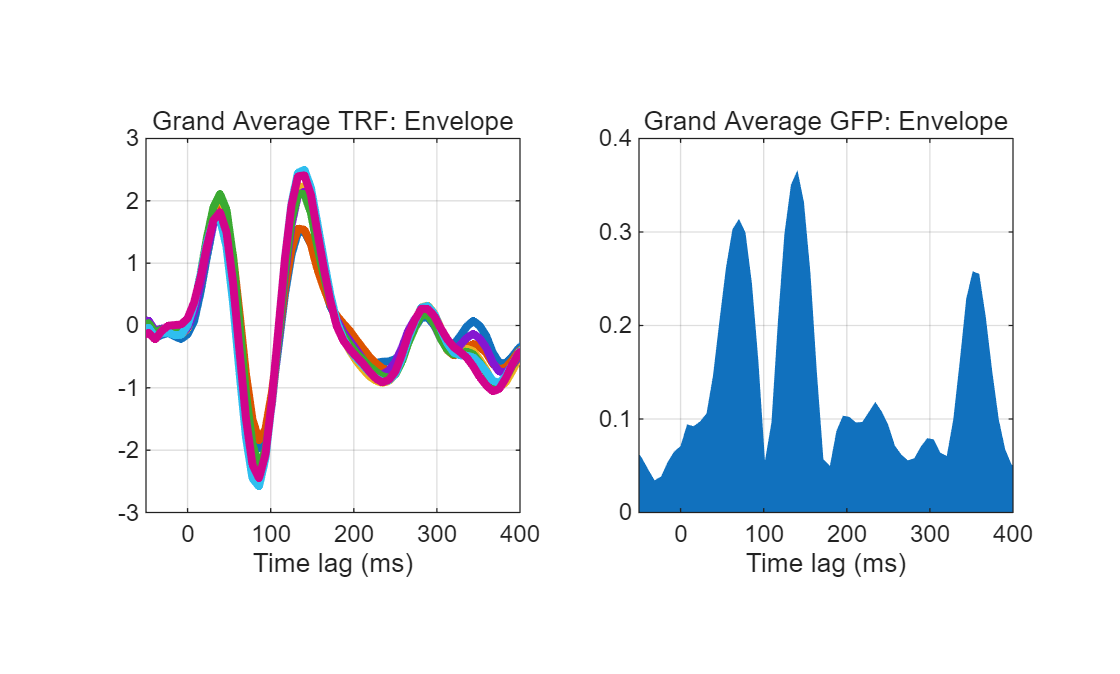

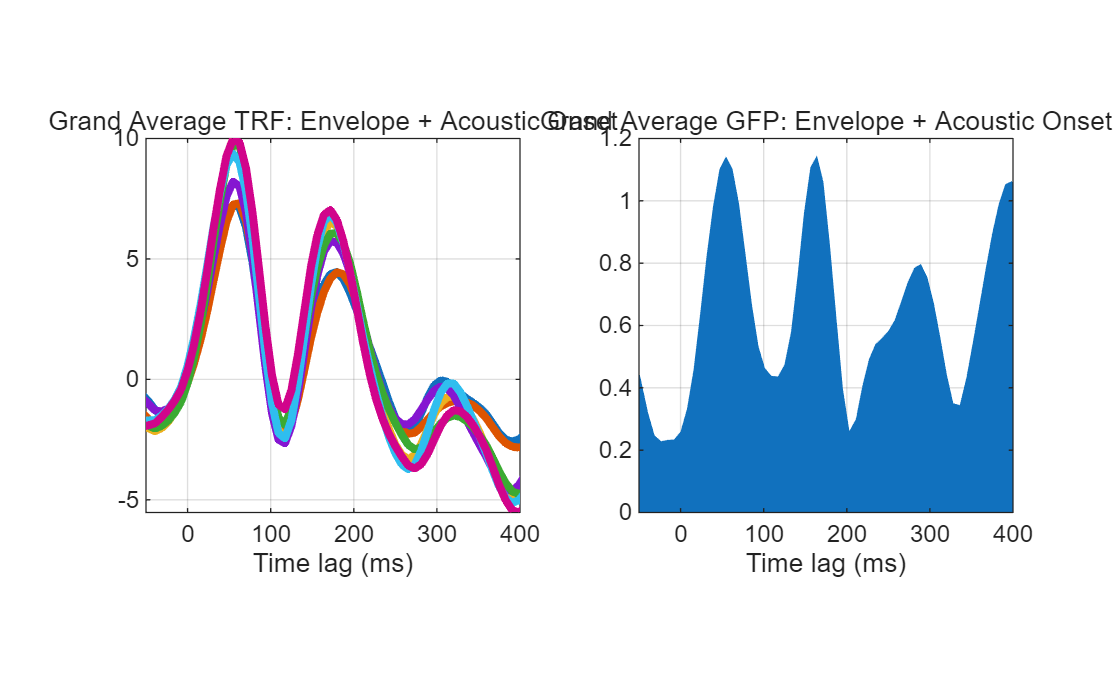

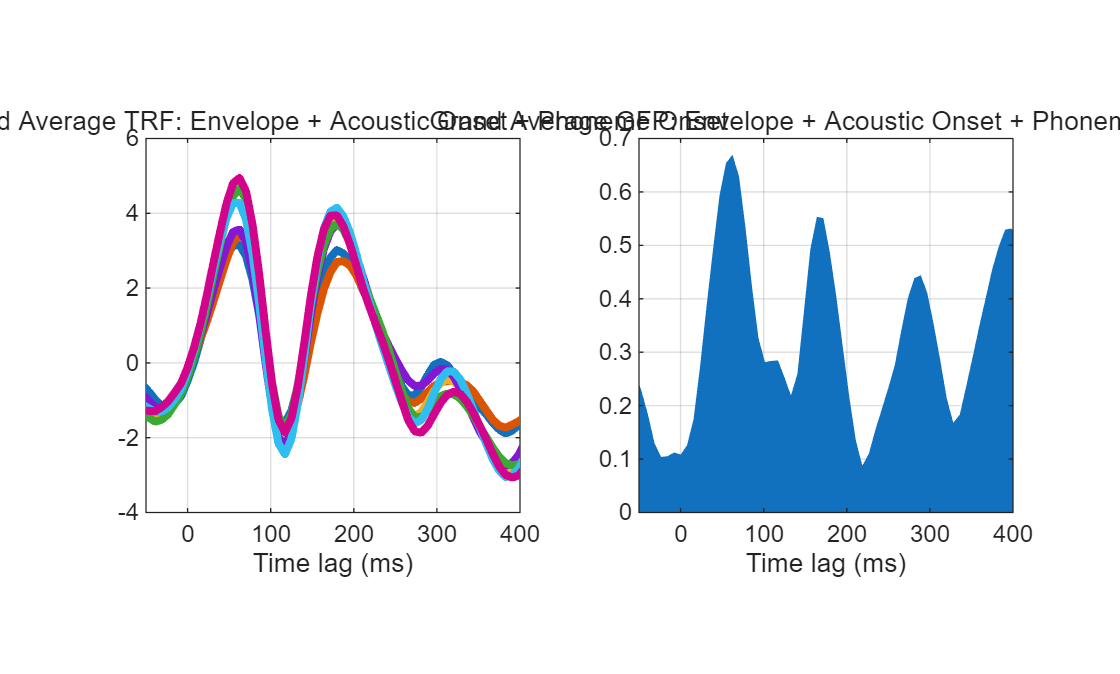


%% plot grand-average TRF for each model
for modelIdx = 1:nModels

    if isempty(grandModel{modelIdx})
        continue
    end

    figure;
    subplot(1,2,1)
    mTRFplot(grandModel{modelIdx}, 'trf', [], selected_ch_idx, Xlims);
    title(sprintf('Grand Average TRF: %s', model_labels{modelIdx}))
    grid on

    subplot(1,2,2)
    mTRFplot(grandModel{modelIdx}, 'gfp', [], selected_ch_idx, Xlims);
    title(sprintf('Grand Average GFP: %s', model_labels{modelIdx}))
    grid on
end

## Step 2: Model tuning (optimization)

Determine optimal lambda

for subIdx = 1: nSubs
    eeg = sub_eegs_trim{subIdx}; 
    [stats,t] = mTRFcrossval(stim_trim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,lambdas,'verbose',0);
        
    % Calculating optimal lambda. Display and store results
    [maxR,bestLambda] = max(squeeze(mean(mean(stats.r,1),3)));
    disp(['EEG prediction correlation (r) = ',num2str(maxR)])
    rAll(subIdx) = maxR;
    rAllElec(:,subIdx) = squeeze(mean(stats.r(:,bestLambda,:),1));
    disp(['Average EEG pred corr (r) = ',num2str(mean(rAll))])

    % Fit TRF model with optimal regularisation parameter
    model = mTRFtrain(stim_trim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,lambdas(bestLambda),'verbose',0);
    
    % Store TRF model
    modelAll_reg(subIdx) = model;
    
    % Plot TRF weights of fine-tuned model
    disp("Forward TRF weights (with regularisation)")
    figure;
    subplot(1,2,1)
    mTRFplot(model,'trf',[],selected_ch_idx, Xlims);
    title('TRF weights')
    grid on
    
    % Plot GFP
    subplot(1,2,2)
    mTRFplot(model,'gfp',[],selected_ch_idx, Xlims);
    title('TRF Global Field Power')
    grid on
end

## **Combining data from multiple subjects**

plotNormFlag = true;
avgModel = mTRFmodelAvg(modelAll_reg,plotNormFlag);

disp("Forward TRF weights (Combining two participants; with regularisation)")

figure;
subplot(1,2,1)
mTRFplot(avgModel,'trf', [], selected_ch_idx, Xlims, [], 1);
title('TRF weights')
grid on

% Plot GFP
subplot(1,2,2)
mTRFplot(avgModel,'gfp',[],selected_ch_idx, Xlims);
title('TRF Global Field Power')
grid on

# Multivariate Forward TRF

% multivariate Forward TRF (unregularised)
for subIdx = 1:nSubs
    eeg = sub_eegs_trim{subIdx};

    stim_all = cell(1, 33);
    resp_all = cell(1, 33);

    for tr = 1:33
        % Combine the 2 stimulus features for this trial -> [T x 2]
        feat1 = stim.data{1, tr};
        feat2 = stim.data{2, tr};
        stim_all{tr} = [feat1, feat2];

        % EEG for this trial
        eeg_trial = eeg.data{tr};

        % Make sure response is [T x nChannels]
        if size(eeg_trial, 1) < size(eeg_trial, 2)
            % likely [nChannels x T], transpose to [T x nChannels]
            eeg_trial = eeg_trial';
        end

        resp_all{tr} = eeg_trial;

        % Optional safety check: stimulus and EEG must have same number of time samples
        if size(stim_all{tr}, 1) ~= size(resp_all{tr}, 1)
            error('Trial %d: stimulus and EEG have mismatched lengths (%d vs %d).', ...
                tr, size(stim_all{tr},1), size(resp_all{tr},1));
        end
    end

    model = mTRFtrain(stim_all, resp_all, eeg.fs, dirTRF, tmin, tmax, 0, 'verbose', 0);
    modelAll_unreg(subIdx) = model;

    figure;
    mTRFplot(model, 'mtrf', 'all', 31, [-100 450]);
    figure;
    mTRFplot(model,'trf','all', 31,[-100,450]);
end

# analysis

## multiple measure anova

subject_ids = cell(nSubs,1);
for i = 1:nSubs
    tok = regexp(eeg_fnames{i}, 'Sub\d+', 'match', 'once');
    if isempty(tok)
        [~, tok, ~] = fileparts(eeg_fnames{i});
    end
    subject_ids{i} = tok;
end

emotion_levels = ["hap", "sad"];   % adjust to your labels
nEmo = numel(emotion_levels);

% analysis window for scalar TRF metric (ms)
stat_tmin = 0;
stat_tmax = 400;

%% =========================
% preallocate outputs
% ==========================
bestLambdaIdx_all = nan(nSubs, 1);   % one best lambda per subject
modelAll_reg = cell(nSubs, nEmo);

% scalar feature for ANOVA:
% mean absolute TRF weight within time window and selected channels
TRF_metric = nan(nSubs, nEmo);

%% =========================
% main loop: one lambda per subject, then fit each emotion
% ==========================
for subIdx = 1:nSubs
    
    eeg = sub_eegs{subIdx};
    
    %% ---------------------------------
    % choose lambda once per subject using ALL blocks
    %% ---------------------------------
    all_idx = 1:numel(eeg.data);
    
    if numel(all_idx) < 2
        error('Subject %d has fewer than 2 total blocks. Cannot run cross-validation.', subIdx);
    end
    
    [stats_all, ~] = mTRFcrossval( ...
        stim.data(stimIdx, all_idx), ...
        eeg.data(all_idx), ...
        eeg.fs, dirTRF, tmin, tmax, lambdas, ...
        'verbose', 0);
    
    mean_r_lambda_all = squeeze(mean(mean(stats_all.r, 1), 3));
    [~, bestLambdaIdx] = max(mean_r_lambda_all);
    bestLambda = lambdas(bestLambdaIdx);
    
    bestLambdaIdx_all(subIdx) = bestLambdaIdx;
    
    fprintf('\nSubject %d (%s): best lambda = %.5g\n', ...
        subIdx, subject_ids{subIdx}, bestLambda);
    
    %% ---------------------------------
    % fit one model per emotion
    %% ---------------------------------
    for emoIdx = 1:nEmo
        
        selected_emotion = emotion_levels(emoIdx);
        idx = strcmp(string(audio_emotions), selected_emotion);
        match_idx = find(idx);
        
        if isempty(match_idx)
            warning('No matching trials found for emotion %s. Skipping.', selected_emotion);
            continue
        end
        
        % fit TRF even if only 1 block
        model = mTRFtrain( ...
            stim.data(stimIdx, match_idx), ...
            eeg.data(match_idx), ...
            eeg.fs, dirTRF, tmin, tmax, bestLambda, ...
            'verbose', 0);
        
        modelAll_reg{subIdx, emoIdx} = model;
        
        %% ---------------------------------
        % extract one comparable scalar TRF metric
        % ---------------------------------
        % model.w is typically [nFeatures x nLags x nChannels]
        W = model.w;
        tvec = model.t;
        
        lag_mask = (tvec >= stat_tmin) & (tvec <= stat_tmax);
        
        if ~any(lag_mask)
            error('No lags fall inside stat_tmin/stat_tmax window.');
        end
        
        % selected_ch_idx should already exist in your workspace
        ch_use = selected_ch_idx(:)';
        
        % robust scalar: mean absolute TRF weight
        metric_val = mean(abs(W(:, lag_mask, ch_use)), 'all', 'omitnan');
        
        TRF_metric(subIdx, emoIdx) = metric_val;
        
        fprintf('  Emotion %s: metric = %.6f\n', selected_emotion, metric_val);
    end
end

%% =========================
% inspect scalar matrix
% ==========================
disp('Scalar TRF metric matrix (subjects x emotions):')
disp(TRF_metric)

%% =========================
% repeated-measures ANOVA table
% ==========================
anovaTbl = array2table(TRF_metric, ...
    'VariableNames', matlab.lang.makeValidName(cellstr(emotion_levels)));

valid_rows = all(~isnan(TRF_metric), 2);
anovaTbl = anovaTbl(valid_rows, :);
subject_ids_valid = subject_ids(valid_rows);

fprintf('Number of complete subjects = %d\n', height(anovaTbl));

anovaTbl_show = anovaTbl;
anovaTbl_show.Subject = subject_ids_valid;
anovaTbl_show = movevars(anovaTbl_show, 'Subject', 'Before', 1);

disp('Data used for ANOVA:')
disp(anovaTbl_show)

if height(anovaTbl) < 2
    error('Not enough complete subjects for repeated-measures ANOVA.');
end

%% =========================
% within-subject design
% ==========================
within = table(categorical(emotion_levels(:)), ...
    'VariableNames', {'Emotion'});

rm = fitrm(anovaTbl, ...
    sprintf('%s-%s ~ 1', ...
    anovaTbl.Properties.VariableNames{1}, ...
    anovaTbl.Properties.VariableNames{end}), ...
    'WithinDesign', within);

ranovaTbl = ranova(rm, 'WithinModel', 'Emotion');

disp('One-way repeated-measures ANOVA results:')
disp(ranovaTbl)

%% =========================
% effect size
% ==========================
row_names = string(ranovaTbl.Properties.RowNames);

effect_idx = find(row_names == "(Intercept):Emotion", 1);
error_idx  = find(row_names == "Error(Emotion)", 1);

if isempty(effect_idx) || isempty(error_idx)
    error('Could not find (Intercept):Emotion or Error(Emotion) in ranovaTbl.');
end

Fval = ranovaTbl.F(effect_idx);
pval = ranovaTbl.pValue(effect_idx);
df1  = ranovaTbl.DF(effect_idx);
df2  = ranovaTbl.DF(error_idx);

ss_effect = ranovaTbl.SumSq(effect_idx);
ss_error  = ranovaTbl.SumSq(error_idx);

eta_p2  = ss_effect / (ss_effect + ss_error);
cohen_f = sqrt(eta_p2 / (1 - eta_p2));

fprintf('\nMain effect of Emotion:\n');
fprintf('F(%g, %g) = %.4f, p = %.6f\n', df1, df2, Fval, pval);
fprintf('Partial eta-squared = %.4f\n', eta_p2);
fprintf('Cohen''s f = %.4f\n', cohen_f);

## calculate effect size

%% automatic effect size calculation: partial eta squared
effectNames = { ...
    '(Intercept):Gender', ...
    '(Intercept):Emotion', ...
    '(Intercept):Style', ...
    '(Intercept):Gender:Emotion', ...
    '(Intercept):Gender:Style', ...
    '(Intercept):Emotion:Style', ...
    '(Intercept):Gender:Emotion:Style'};

errorNames = { ...
    'Error(Gender)', ...
    'Error(Emotion)', ...
    'Error(Style)', ...
    'Error(Gender:Emotion)', ...
    'Error(Gender:Style)', ...
    'Error(Emotion:Style)', ...
    'Error(Gender:Emotion:Style)'};

eta_p2 = nan(numel(effectNames),1);
Fvals = nan(numel(effectNames),1);
pvals = nan(numel(effectNames),1);
df1 = nan(numel(effectNames),1);
df2 = nan(numel(effectNames),1);

for i = 1:numel(effectNames)
    effIdx = strcmp(ranovaTbl.Properties.RowNames, effectNames{i});
    errIdx = strcmp(ranovaTbl.Properties.RowNames, errorNames{i});
    
    if any(effIdx) && any(errIdx)
        SS_effect = ranovaTbl.SumSq(effIdx);
        SS_error  = ranovaTbl.SumSq(errIdx);
        
        if ~isnan(SS_effect) && ~isnan(SS_error) && (SS_effect + SS_error) > 0
            eta_p2(i) = SS_effect / (SS_effect + SS_error);
        end
        
        Fvals(i) = ranovaTbl.F(effIdx);
        pvals(i) = ranovaTbl.pValue(effIdx);
        df1(i) = ranovaTbl.DF(effIdx);
        df2(i) = ranovaTbl.DF(errIdx);
    end
end

effectTbl = table( ...
    string(effectNames(:)), df1, df2, Fvals, pvals, eta_p2, ...
    'VariableNames', {'Effect','DF1','DF2','F','pValue','partialEtaSq'});

disp('Effect size table (partial eta squared):')
disp(effectTbl)

%% optional post hoc exploration
fprintf('\nCondition means (raw r):\n')
for condIdx = 1:nConds
    fprintf('%s : %.6f\n', condTable.ConditionName(condIdx), ...
        mean(R(:,condIdx), 'omitnan'));
end

## estimate target participant number

%% approximate sample size estimation from pilot partial eta squared
% Notes:
% - This is a planning approximation for repeated-measures ANOVA effects.
% - Pilot effect sizes from very small N are unstable, so treat results cautiously.
% - Recommended to use this as a rough guide, then choose a slightly larger N.

alpha = 0.05;          % significance level
targetPower = 0.80;    % desired power
Ngrid = 5:100;         % candidate participant counts to search

% convert partial eta squared to Cohen's f
cohens_f = sqrt(effectTbl.partialEtaSq ./ (1 - effectTbl.partialEtaSq));

% preallocate
targetN = nan(height(effectTbl),1);
achievedPower = nan(height(effectTbl),1);

for i = 1:height(effectTbl)
    
    f = cohens_f(i);
    df1_i = effectTbl.DF1(i);
    
    % skip invalid cases
    if isnan(f) || isinf(f) || f <= 0 || isnan(df1_i) || df1_i <= 0
        continue
    end
    
    for N = Ngrid
        % for your current repeated-measures output, denominator df is N-1
        % because each tested effect has DF1 = 1 in a 2x2x2 design
        df2_i = N - 1;
        
        % critical F under H0
        Fcrit = finv(1 - alpha, df1_i, df2_i);
        
        % approximate noncentrality parameter
        lambda_ncp = N * f^2;
        
        % power = P(F > Fcrit | H1)
        thisPower = 1 - ncfcdf(Fcrit, df1_i, df2_i, lambda_ncp);
        
        if thisPower >= targetPower
            targetN(i) = N;
            achievedPower(i) = thisPower;
            break
        end
    end
end

% append to table
effectTbl.cohens_f = cohens_f;
effectTbl.targetN_80power = targetN;
effectTbl.estimatedPowerAtTargetN = achievedPower;

disp('Effect table with approximate target sample size:')
disp(effectTbl)

# save models as single mat file

% models = struct();
% 
% models.modelAll_unreg = modelAll_unreg;
% models.modelAll_reg = modelAll_reg;
% avgModel_save(1) = avgModel;
% models.avgModel_reg = avgModel_save;
% models.feature = stimName;
% models.filenames = eeg_fnames;
% models.lambdas = lambdas;
% models.chanlocs = eeg.chanlocs;
% 
% outname = sprintf('dataTRF_%s.mat', char(stimName));
% outpath = fullfile(indir, outname);
% save(outpath, "models");